clear

splineSpace.degree = 4;
splineSpace.nodes = [0 1 2 3 4 5];
splineSpace.continuityVector = [-1 3 2 1 0 -1];

b = bspline(splineSpace)
b.basis.functions

% fplot(b.basis.functions,[-1 6])
% axis equal

[b, T] = b.bezierExtraction()
clear

splineSpace.degree = 4;
splineSpace.nodes = [0 1 2 3 4 5];
splineSpace.continuityVector = [-1 3 2 1 0 -1];

b = bspline(splineSpace)
b.basis.functions

% fplot(b.basis.functions,[-1 6])
% axis equal

[b, T] = b.bezierExtraction()

T{end}

clear

splineSpace.degree = 3;
splineSpace.nodes = [0 1/2 1];
splineSpace.continuityVector = [-1 2 -1];

b = bspline(splineSpace)

b =   bspline with properties:

              degree: 3
    continuityVector: [-1 2 -1]
            numcells: 2
               nodes: [0 0.5000 1]
          knotVector: [0 0 0 0 0.5000 1 1 1 1]
               basis: [1×1 struct]


b.basis.functions

$$ans = \left(\begin{array}{c} \left\{ \begin{array}{cl} -{\left(2\,\xi -1\right)}^{3} & \text{ if }\xi \in \left[0,\frac{1}{2}\right)\\ 0 & \mathrm{otherwise} \end{array}\right.\\ \left\{ \begin{array}{cl} 2\,\xi \,\left(7\,\xi^{2}-9\,\xi +3\right) & \text{ if }\xi \in \left[0,\frac{1}{2}\right)\\ -\left(2\,\xi -2\right)\,{\left(\xi -1\right)}^{2} & \text{ if }\xi \in \left[\frac{1}{2},1\right)\\ 0 & \mathrm{otherwise} \end{array}\right.\\ \left\{ \begin{array}{cl} -2\,\xi^{2}\,\left(4\,\xi -3\right) & \text{ if }\xi \in \left[0,\frac{1}{2}\right)\\ 2\,\left(4\,\xi -1\right)\,{\left(\xi -1\right)}^{2} & \text{ if }\xi \in \left[\frac{1}{2},1\right)\\ 0 & \mathrm{otherwise} \end{array}\right.\\ \left\{ \begin{array}{cl} 2\,\xi^{3} & \text{ if }\xi \in \left[0,\frac{1}{2}\right)\\ -14\,\xi^{3}+24\,\xi^{2}-12\,\xi +2 & \text{ if }\xi \in \left[\frac{1}{2},1\right)\\ 0 & \mathrm{otherwise} \end{array}\right.\\ \left\{ \begin{array}{cl} {\left(2\,\xi -1\right)}^{3} & \text{ if }\xi \in \left[\frac{1}{2},1\right)\\ 0 & \mathrm{otherwise} \end{array}\right. \end{array}\right)$$

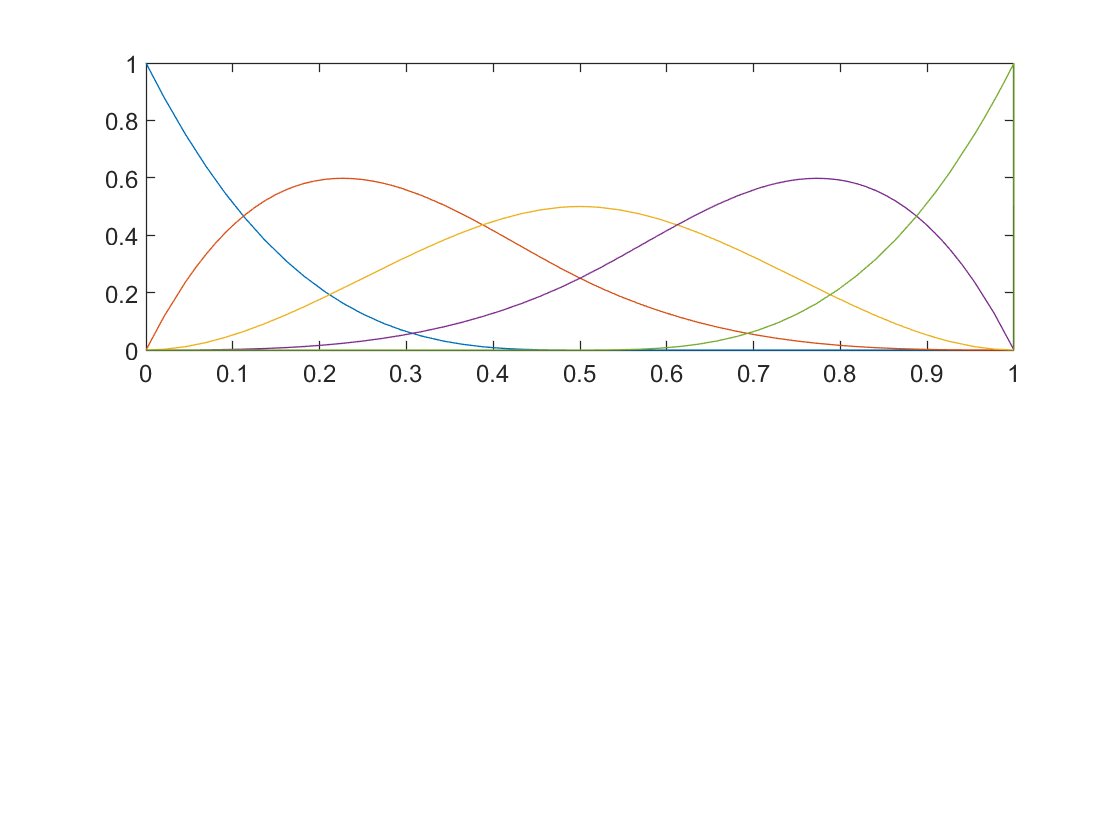


figure
subplot(2,1,1)
fplot(b.basis.functions,[0 1])


% fplot(b.basis.functions,[-1 6])
% axis equal

[bez, T] = b.bezierExtraction()

bez =   bspline with properties:

              degree: 3
    continuityVector: [-1 0 -1]
            numcells: 2
               nodes: [0 0.5000 1]
          knotVector: [0 0 0 0 0.5000 0.5000 0.5000 1 1 1 1]
               basis: [1×1 struct]


T = 4×1 cell array
    {10×8 sym}
    { 9×7 sym}
    { 8×6 sym}
    { 7×5 sym}



M = T{end}

$$M = \left(\begin{array}{ccccc} 1 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0\\ 0 & \frac{1}{2} & \frac{1}{2} & 0 & 0\\ 0 & \frac{1}{4} & \frac{1}{2} & \frac{1}{4} & 0\\ 0 & 0 & \frac{1}{2} & \frac{1}{2} & 0\\ 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 1 \end{array}\right)$$

clear

splineSpace.degree = 2;
splineSpace.nodes = [0 1 2 3];
splineSpace.continuityVector = [-1 1 1 -1];

b = bspline(splineSpace)

b =   bspline with properties:

              degree: 2
    continuityVector: [-1 1 1 -1]
            numcells: 3
               nodes: [0 1 2 3]
          knotVector: [0 0 0 1 2 3 3 3]
               basis: [1×1 struct]


b.basis.functions

$$ans = \left(\begin{array}{c} \left\{ \begin{array}{cl} {\left(\xi -1\right)}^{2} & \text{ if }\xi \in \left[0,1\right)\\ 0 & \mathrm{otherwise} \end{array}\right.\\ \left\{ \begin{array}{cl} -\frac{\xi \,\left(3\,\xi -4\right)}{2} & \text{ if }\xi \in \left[0,1\right)\\ \left(\frac{\xi }{2}-1\right)\,\left(\xi -2\right) & \text{ if }\xi \in \left[1,2\right)\\ 0 & \mathrm{otherwise} \end{array}\right.\\ \left\{ \begin{array}{cl} \frac{\xi^{2}}{2} & \text{ if }\xi \in \left[0,1\right)\\ -\xi^{2}+3\,\xi -\frac{3}{2} & \text{ if }\xi \in \left[1,2\right)\\ \left(\frac{\xi }{2}-\frac{3}{2}\right)\,\left(\xi -3\right) & \text{ if }\xi \in \left[2,3\right)\\ 0 & \mathrm{otherwise} \end{array}\right.\\ \left\{ \begin{array}{cl} \left(\frac{\xi }{2}-\frac{1}{2}\right)\,\left(\xi -1\right) & \text{ if }\xi \in \left[1,2\right)\\ -\frac{3\,\xi^{2}}{2}+7\,\xi -\frac{15}{2} & \text{ if }\xi \in \left[2,3\right)\\ 0 & \mathrm{otherwise} \end{array}\right.\\ \left\{ \begin{array}{cl} {\left(\xi -2\right)}^{2} & \text{ if }\xi \in \left[2,3\right)\\ 0 & \mathrm{otherwise} \end{array}\right. \end{array}\right)$$


% figure
% subplot(2,1,1)
% fplot(b.basis.functions,[0 3])

% fplot(b.basis.functions,[-1 6])
% axis equal

[bez, T] = b.bezierExtraction("Scott")

bez =   bspline with properties:

              degree: 2
    continuityVector: [-1 0 0 -1]
            numcells: 3
               nodes: [0 1 2 3]
          knotVector: [0 0 0 1 1 2 2 3 3 3]
               basis: [1×1 struct]


T = 3×1 cell array
    {9×7 sym}
    {8×6 sym}
    {7×5 sym}



M = T{end}

$$M = \left(\begin{array}{ccccc} 1 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0\\ 0 & \frac{1}{2} & \frac{1}{2} & 0 & 0\\ 0 & 0 & 1 & 0 & 0\\ 0 & 0 & \frac{1}{2} & \frac{1}{2} & 0\\ 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 1 \end{array}\right)$$

M = transpose(M)

$$M = \left(\begin{array}{ccccccc} 1 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 1 & \frac{1}{2} & 0 & 0 & 0 & 0\\ 0 & 0 & \frac{1}{2} & 1 & \frac{1}{2} & 0 & 0\\ 0 & 0 & 0 & 0 & \frac{1}{2} & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 1 \end{array}\right)$$


% function getPiecwiseDomains
N = b.basis.functions

$$N = \left(\begin{array}{c} \left\{ \begin{array}{cl} {\left(\xi -1\right)}^{2} & \text{ if }\xi \in \left[0,1\right)\\ 0 & \mathrm{otherwise} \end{array}\right.\\ \left\{ \begin{array}{cl} -\frac{\xi \,\left(3\,\xi -4\right)}{2} & \text{ if }\xi \in \left[0,1\right)\\ \left(\frac{\xi }{2}-1\right)\,\left(\xi -2\right) & \text{ if }\xi \in \left[1,2\right)\\ 0 & \mathrm{otherwise} \end{array}\right.\\ \left\{ \begin{array}{cl} \frac{\xi^{2}}{2} & \text{ if }\xi \in \left[0,1\right)\\ -\xi^{2}+3\,\xi -\frac{3}{2} & \text{ if }\xi \in \left[1,2\right)\\ \left(\frac{\xi }{2}-\frac{3}{2}\right)\,\left(\xi -3\right) & \text{ if }\xi \in \left[2,3\right)\\ 0 & \mathrm{otherwise} \end{array}\right.\\ \left\{ \begin{array}{cl} \left(\frac{\xi }{2}-\frac{1}{2}\right)\,\left(\xi -1\right) & \text{ if }\xi \in \left[1,2\right)\\ -\frac{3\,\xi^{2}}{2}+7\,\xi -\frac{15}{2} & \text{ if }\xi \in \left[2,3\right)\\ 0 & \mathrm{otherwise} \end{array}\right.\\ \left\{ \begin{array}{cl} {\left(\xi -2\right)}^{2} & \text{ if }\xi \in \left[2,3\right)\\ 0 & \mathrm{otherwise} \end{array}\right. \end{array}\right)$$

B = bez.basis.functions

$$B = \left(\begin{array}{c} \left\{ \begin{array}{cl} {\left(\xi -1\right)}^{2} & \text{ if }\xi \in \left[0,1\right)\\ 0 & \mathrm{otherwise} \end{array}\right.\\ \left\{ \begin{array}{cl} -2\,\xi \,\left(\xi -1\right) & \text{ if }\xi \in \left[0,1\right)\\ 0 & \mathrm{otherwise} \end{array}\right.\\ \left\{ \begin{array}{cl} \xi^{2} & \text{ if }\xi \in \left[0,1\right)\\ {\left(\xi -2\right)}^{2} & \text{ if }\xi \in \left[1,2\right)\\ 0 & \mathrm{otherwise} \end{array}\right.\\ \left\{ \begin{array}{cl} -2\,\left(\xi -1\right)\,\left(\xi -2\right) & \text{ if }\xi \in \left[1,2\right)\\ 0 & \mathrm{otherwise} \end{array}\right.\\ \left\{ \begin{array}{cl} {\left(\xi -1\right)}^{2} & \text{ if }\xi \in \left[1,2\right)\\ {\left(\xi -3\right)}^{2} & \text{ if }\xi \in \left[2,3\right)\\ 0 & \mathrm{otherwise} \end{array}\right.\\ \left\{ \begin{array}{cl} -2\,\left(\xi -2\right)\,\left(\xi -3\right) & \text{ if }\xi \in \left[2,3\right)\\ 0 & \mathrm{otherwise} \end{array}\right.\\ \left\{ \begin{array}{cl} {\left(\xi -2\right)}^{2} & \text{ if }\xi \in \left[2,3\right)\\ 0 & \mathrm{otherwise} \end{array}\right. \end{array}\right)$$



N_conditions = cell(length(N),1);
for ii = 1:length(N)
    % ii = 1
    N_parts = children(N(ii))
    
    N_conditions{ii} = N_parts(1:end-1,2)
end

$$N\_parts = \left(\begin{array}{cc} {\left(\xi -1\right)}^{2} & \xi \in \left[0,1\right)\\ 0 & \mathrm{TRUE} \end{array}\right)$$

N_conditions = 5×1 cell array
    {1×1 sym   }
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


$$N\_parts = \left(\begin{array}{cc} -\frac{\xi \,\left(3\,\xi -4\right)}{2} & \xi \in \left[0,1\right)\\ \left(\frac{\xi }{2}-1\right)\,\left(\xi -2\right) & \xi \in \left[1,2\right)\\ 0 & \mathrm{TRUE} \end{array}\right)$$

N_conditions = 5×1 cell array
    {1×1 sym   }
    {2×1 sym   }
    {0×0 double}
    {0×0 double}
    {0×0 double}


$$N\_parts = \left(\begin{array}{cc} \frac{\xi^{2}}{2} & \xi \in \left[0,1\right)\\ -\xi^{2}+3\,\xi -\frac{3}{2} & \xi \in \left[1,2\right)\\ \left(\frac{\xi }{2}-\frac{3}{2}\right)\,\left(\xi -3\right) & \xi \in \left[2,3\right)\\ 0 & \mathrm{TRUE} \end{array}\right)$$

N_conditions = 5×1 cell array
    {1×1 sym   }
    {2×1 sym   }
    {3×1 sym   }
    {0×0 double}
    {0×0 double}


$$N\_parts = \left(\begin{array}{cc} \left(\frac{\xi }{2}-\frac{1}{2}\right)\,\left(\xi -1\right) & \xi \in \left[1,2\right)\\ -\frac{3\,\xi^{2}}{2}+7\,\xi -\frac{15}{2} & \xi \in \left[2,3\right)\\ 0 & \mathrm{TRUE} \end{array}\right)$$

N_conditions = 5×1 cell array
    {1×1 sym   }
    {2×1 sym   }
    {3×1 sym   }
    {2×1 sym   }
    {0×0 double}


$$N\_parts = \left(\begin{array}{cc} {\left(\xi -2\right)}^{2} & \xi \in \left[2,3\right)\\ 0 & \mathrm{TRUE} \end{array}\right)$$

N_conditions = 5×1 cell array
    {1×1 sym}
    {2×1 sym}
    {3×1 sym}
    {2×1 sym}
    {1×1 sym}



for e = 1:b.numcells
    elemCenter = sum(b.nodes(e:e+1))/2;
    inDomain = false(length(N_conditions),1);
    for ii = 1:length(N_conditions)
        condition = N_conditions{ii};
        inDomain(ii) = any(isAlways(subs(condition,symvar(condition),elemCenter)));
    end
    isBasisSupported{e} = inDomain;
    supportedBases{e} = find(inDomain);
end

for e = 1:b.numcells
    supportedBezBases = [((e-1)*b.degree + 1) : (e*b.degree+1)]
    C{e} = M(supportedBases{e},supportedBezBases)
end

supportedBezBases =      1     2     3


C = 1×1 cell array
    {3×3 sym}


supportedBezBases =      3     4     5


C = 1×2 cell array
    {3×3 sym}    {3×3 sym}


supportedBezBases =      5     6     7


C = 1×3 cell array
    {3×3 sym}    {3×3 sym}    {3×3 sym}


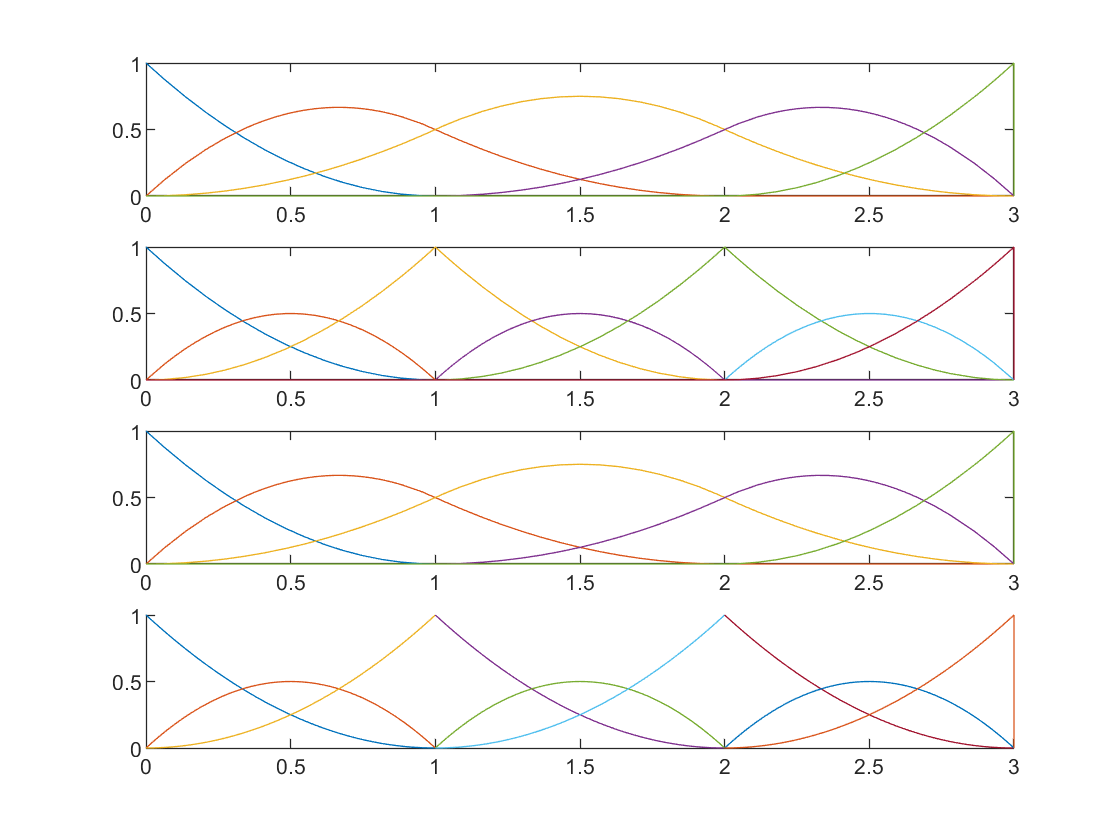


figure
subplot(4,1,1)
fplot(b.basis.functions, [0 3])

subplot(4,1,2)
fplot(bez.basis.functions, [0 3])

subplot(4,1,3)
fplot(M*bez.basis.functions,[0 3])

subplot(4,1,4)
hold on
for e = 1:b.numcells
    fplot(inv(C{e}) * b.basis.functions(supportedBases{e}),[b.nodes(e) b.nodes(e+1)])
end

clear
splineSpace.degree = 2;
splineSpace.nodes = [0 1 2 3];
splineSpace.continuityVector = [-1 1 1 -1];

b = bspline(splineSpace)

b =   bspline with properties:

              degree: 2
    continuityVector: [-1 1 1 -1]
            numcells: 3
               nodes: [0 1 2 3]
          knotVector: [0 0 0 1 2 3 3 3]
               basis: [1×1 struct]



D = b.lagrangeExtraction()
D'

[eCONN,x] = generateMesh(0,3,3,2)
L = basisFunction("Lagrange",2,sym("xi","real"),[-1 1])
ELEM = createElements(eCONN,x,L)

F = sym(zeros(max(eCONN(:)),1));
for e = 1:length(ELEM)
    condition = ELEM(e).GDomain(1) <= sym("x") <= ELEM(e).GDomain(2);
    bFun = formula(ELEM(e).GBasisFuns);
    for n = 1:length(ELEM(e).GNodes)
        F(eCONN(e,n)) = F(eCONN(e,n)) + piecewise(condition,bFun(n),0);
    end
end

F

D * F
figure
subplot(2,1,1)
fplot(F,[min(x) max(x)])
subplot(2,1,2)
fplot(D*F,[min(x) max(x)])


clear

splineSpace.degree = 2;
splineSpace.nodes = [0 1 2 3];
splineSpace.continuityVector = [-1 1 1 -1];

b = bspline(splineSpace)
